# Train deepGLM for binary response data

Load a simulation dataset. The dataset has following information:

- Training: 4500 observations

- Test: 500 observation

- Number of covariates: 10

- Number of covariates used to generate data: 5

- Percentage of '1' responses in test data: 53.2%

`d = 10;`

`X = unifrnd(0,2,n,d);`

`muy = 2 + (X(:,1)+X(:,2)).^2 - 5*X(:,3).*X(:,4) - 2*X(:,5);`

`p = exp(muy)./(1+exp(muy));`

`y = double(p>0.5);`

clear
clc
load('../Data/DataSimulationBinary.mat')

## **Training Phase**

mdl = deepGLMfit(X,y,... 
                 'Distribution','binomial',...
                 'Network',10,... 
                 'Lrate',0.01,...           
                 'Verbose',10,...             % Display training result each iteration
                 'BatchSize',size(X,1),...    % Use entire training data as mini-batch
                 'MaxEpoch',10000,...
                 'Patience',50,...            % Higher patience values could lead to overfitting
                 'Seed',100);

Initial LB: -0.92505
---------- Training Phase ----------
Epoch: 9   -   Current LB: -0.76198
Epoch: 19   -   Current LB: -0.75512
Epoch: 29   -   Current LB: -0.75477
Epoch: 39   -   Current LB: -0.75265
Epoch: 49   -   Current LB: -0.75069
Epoch: 59   -   Current LB: -0.7485
Epoch: 69   -   Current LB: -0.74652
Epoch: 79   -   Current LB: -0.74457
Epoch: 89   -   Current LB: -0.74255
Epoch: 99   -   Current LB: -0.74062
Epoch: 109   -   Current LB: -0.73866
Epoch: 119   -   Current LB: -0.73665
Epoch: 129   -   Current LB: -0.73455
Epoch: 139   -   Current LB: -0.73238
Epoch: 149   -   Current LB: -0.73021
Epoch: 159   -   Current LB: -0.72781
Epoch: 169   -   Current LB: -0.72552
Epoch: 179   -   Current LB: -0.72311
Epoch: 189   -   Current LB: -0.72018
Epoch: 199   -   Current LB: -0.71729
Epoch: 209   -   Current LB: -0.71414
Epoch: 219   -   Current LB: -0.71068
Epoch: 229   -   Current LB: -0.70684
Epoch: 239   -   Current LB: -0.70227
Epoch: 249   -   Current LB: -0.69657
Epoc

Plot convergence path of lowerbound

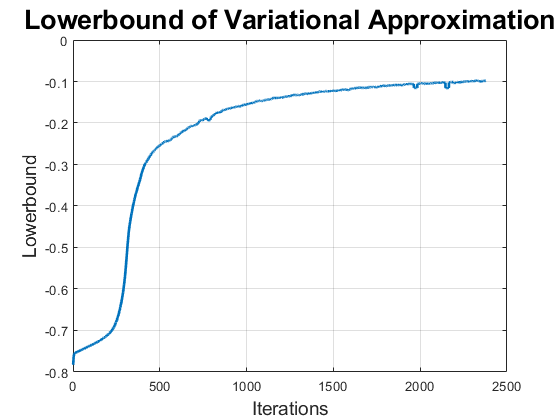

plot(mdl.out.lbBar,'LineWidth',2)
title('Lowerbound of Variational Approximation','FontSize',20)
xlabel('Iterations','FontSize',14,'FontWeight','bold')
ylabel('Lowerbound','FontSize',14,'FontWeight','bold')
grid on             

## **Variable Selection**

We use only first 5 variables to generate the training data, then we expect that after the training phase, 

the group Lasso coefficients (shrinkage coefficients) would be smaller than the coeffificents of last 5 variables.

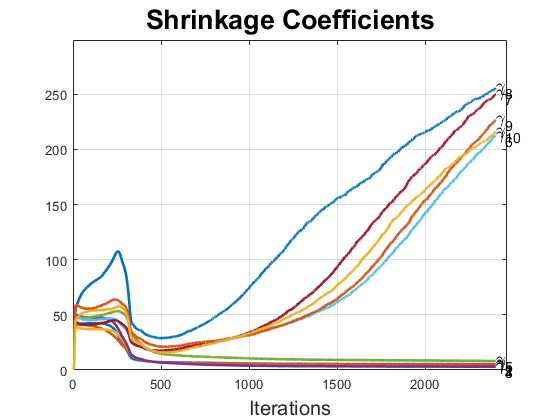

deepGLMplot('Shrinkage',mdl.out.shrinkage,...
            'Title','Shrinkage Coefficients',...
            'Xlabel','Iterations',...
            'LineWidth',2);

The Shrinkage plot clearly shows that deepGLM has done a good job in variable selection.

## **Prediction**

We can make prediction for new data with **deepGLMpredict. **The output of deepGLMpredict is a structure with fields:

- yNN : Output from Neuron Network

- yProb: The probability vector after passing yNN to sigmoid function

- yhat: Binary vector contains prediction values of new observations using yProd and cut-off probability specified in 'cutoff' option of **deepGLMfit**

Pred1 = deepGLMpredict(mdl,X_test);

We can also specify vector of true response for model evaluation (to compare predictive performances of different models)

Pred2 = deepGLMpredict(mdl,X_test,'ytest',y_test);
disp(['PPS on test data using deepGLM: ',num2str(Pred2.pps)]);

PPS on test data using deepGLM: 0.075661


disp(['Classification rate on test data using deepGLM: ',num2str(Pred2.accuracy*100),'%']);

Classification rate on test data using deepGLM: 97%


Let's compare the classification rate made by deepGLM with Logistic regression

mdlLR = fitglm(X,y,'Distribution','binomial','Link','logit');
yProb = predict(mdlLR,X_test);
yHat = double(yProb>=0.5);
accuracy = sum(yHat==y_test)/length(y_test);
disp(['Classification rate on test using Logistic Regression: ',num2str(accuracy*100),'%']);

Classification rate on test using Logistic Regression: 91.6%


We can use deepGLMplot to plot ROC curve for a trained deepGLM model on a test dataset

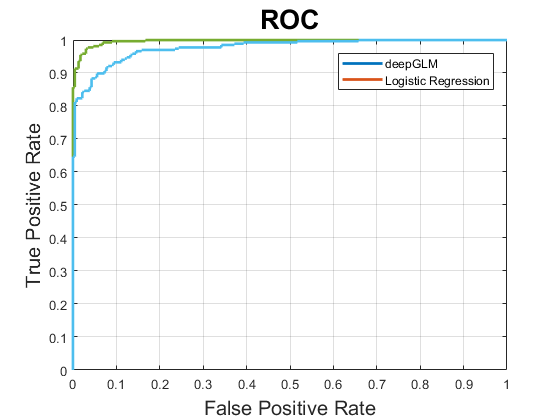

deepGLMplot('ROC',[Pred2.yProb,yProb],...
            'ytest',y_test,...
            'Title','ROC',...
            'Xlabel','False Positive Rate',...
            'Ylabel','True Positive Rate',...
            'legend',{'deepGLM','Logistic Regression'})